This script is to compute power differences between contralateral and ipsilateral posterior electrodes, with respect to the first-attended side, with the data structure computed using Deci's pre-processing pipeline. 

Note that the artifactual trials need to be rejected (happening in run_prepfortf_fordeci), and data needs to be redefined as it not yet locked to stimulus or response samples. 

Also note that trials with high RTs are not yet being removed from the analysis

#### Select subjects

clearvars;
filepath        = 'D:\Shrey\silent_wm_e02\ProcessedData\Artifact';
savepath        = 'D:\Shrey\silent_wm_e02\ProcessedData\PowerDifferences\JohnsRejection';
subjects        = CleanDir(filepath);

fakeUI          = figure;
fakeUI.UserData = subjects;
fakeUI.Visible  =  'off';
select_labels(fakeUI,[],subjects);
waitfor(findall(0,'Name','Select Labels'),'BeingDeleted','on');
subjects        = fakeUI.UserData;
close(fakeUI);

layout          = 'C:\Users\Rob Reinhart\Documents\GitHub\Deci\Function\Gen_Fun\easycap_rob_eye.mat';


**Hemi-field controlled posterior power analysis**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% type of data to analyse 
version = [];
cipower.dataprep.hemi           = true;
cipower.dataprep.correct        = true;
cipower.dataprep.incorrect      = false;
cipower.dataprep.laplace        = true;
cipower.dataprep.locks          = [1 2]; % [1],[2],[3],[1 2],[1 2 3]; as of now I only need locks 1 and 2 (stim onset and d3 onset)
cipower.dataprep.cutlatency     = [-1 5];

% frequency decomposition parameters
cipower.decompose.freq          = 2:50; 
cipower.decompose.width         = linspace(3,13,length(cipower.decompose.freq));
cipower.decompose.time          = -0.05:0.001:1.25;
cipower.decompose.bstoi         = [-0.2 0];
cipower.decompose.output        = 'pow';
cipower.decompose.keeptrials    = 'no';

% cipower.decompose.chan          = {'AF7', 'AF3', 'AFz','AF4','AF8','F7','F5','F3','F1','Fz','F2','F4','F6','F8','FT7','FC5','FC3','FC1','FCz','FC2','FC4','FC6','FT8','T7','C5','C3','C1','Cz','C2','C4','C6','T8','TP7','CP5','CP3','CP1','CPz','CP2','CP4','CP6','TP8','P7','P5',...
% 'P3','P1','Pz','P2','P4','P6','P8','PO7','PO3','POz','PO4','PO8','O1','Oz','O2'};
cipower.decompose.chan          = {'P7','P5','P3','P1','Pz','P2','P4','P6','P8','PO7','PO3','POz','PO4','PO8','O1','Oz','O2'};
% cipower.decompose.chan          = {'PO7','PO3','PO4','PO8','O1','O2'};
cipower.decompose.hilbert       = false; % if unchecked, wavelet decomposition will be run by default (width=3:13; gwidth=4).

cipower.baseline = cipower.decompose;
cipower.baseline.time = -0.2:0.001:0;

% Call the subroutine
PCom                            = true;         
if exist('PComs') == 0 && PCom
    PComs(1) = parfeval(@rand,0,1);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 20).



if PCom == true
    for subject= 1:length(subjects)
        director = [filepath filesep subjects{subject} filesep subjects{subject}];
        PComs(end+1)= parfeval(@subroutine_poweranalysis_fordeci,0,subjects{subject},filepath,savepath,version,cipower);
    end
else
    for subject= 1:length(subjects)
        director = [filepath filesep subjects{subject} filesep subjects{subject}];
        subroutine_poweranalysis_fordeci(subjects{subject},filepath,savepath,version,cipower);
    end
end


#### Plot the hemisphere differences

version = [];
correcttrials   = true;
incorrecttrials = false;
showlaplace     = true;
showhilbert     = false;
showhemi        = true;
imgpath = 'D:\Shrey\silent_wm_e02\ProcessedData\PowerDifferences\JohnsRejection';

if showhemi == true
    version = [version '_hemi'];
end
if correcttrials == true
    version = [version '_correct'];
end
if incorrecttrials == true
    version = [version '_incorrect'];
end
if showlaplace == true
    version = [version '_laplace'];
end

if showhilbert == true
    version = [version '_hilbert'];
end

for sub = 1:length(subjects)
    subnum = strsplit(subjects{sub},'_');
    director = [imgpath filesep subnum{1} version]; 
    diff(sub).d1  = load([director '_lock1_cipower.mat'],'difference','contra','ipsi');
    diff(sub).d3  = load([director '_lock2_cipower.mat'],'difference','contra','ipsi');
 
    f = figure('units','normalized','outerposition',[0 0 0.5 1]);
    f.Visible = 'On';
    
    subplot(3,2,1)
    cfg = []; %cfg.frequency = [6 16];
    cfg.latency = [0.25 1.25];
    plotfun.xlabel = {'D1 Start', 'D1 End'};
    plotfun.caxis  = [-3 3];
    plotfun.title  = [subnum{1} ' Contra D1'];
    data = ft_selectdata(cfg,diff(sub).d1.contra);
    subplotter(data,plotfun);
    single.d1.contra{sub} = data;
    clear data;
    
    subplot(3,2,2)
    cfg = []; %cfg.frequency = [6 16];
    cfg.latency = [0 1];
    plotfun.xlabel = {'D3 Start', 'D3 End'};
    plotfun.caxis  = [-3 3];
    plotfun.title  = [subnum{1} ' Contra D3'];
    data = ft_selectdata(cfg,diff(sub).d3.contra);
    subplotter(data,plotfun);
    single.d3.contra{sub} = data;
    clear data;
    
    subplot(3,2,3)
    cfg = []; %cfg.frequency = [6 16];
    cfg.latency = [0.25 1.25];
    plotfun.xlabel = {'D1 Start', 'D1 End'};
    plotfun.caxis  = [-3 3];
    plotfun.title  = [subnum{1} ' Ipsi D1'];
    data = ft_selectdata(cfg,diff(sub).d1.ipsi);
    subplotter(data,plotfun);
    single.d1.ipsi{sub} = data;
    clear data;
    
    subplot(3,2,4)
    cfg = []; %cfg.frequency = [6 16];
    cfg.latency = [0 1];
    plotfun.xlabel = {'D3 Start', 'D3 End'};
    plotfun.caxis  = [-3 3];
    plotfun.title  = [subnum{1} ' Ipsi D3'];
    data = ft_selectdata(cfg,diff(sub).d3.ipsi);
    subplotter(data,plotfun);
    single.d3.ipsi{sub} = data;
    clear data;
    
    subplot(3,2,5)
    cfg = []; %cfg.frequency = [6 16];
    cfg.latency = [0.25 1.25];
    plotfun.xlabel = {'D1 Start', 'D1 End'};
    plotfun.caxis  = [-1.5 1.5];
    plotfun.title  = [subnum{1} ' Difference D1'];
    data = ft_selectdata(cfg,diff(sub).d1.difference);
    subplotter(data,plotfun);
    data.powspctrm = reshape(data.powspctrm,1,size(data.powspctrm,1),size(data.powspctrm,2));
    data.dimord = 'chan_freq_time';
    single.d1.difference{sub} = data;
    clear data;
    
    subplot(3,2,6)
    cfg = []; %cfg.frequency = [6 16];
    cfg.latency = [0 1];
    plotfun.xlabel = {'D3 Start', 'D3 End'};
    plotfun.caxis  = [-1.5 1.5];
    plotfun.title  = [subnum{1} ' Difference D3'];
    data = ft_selectdata(cfg,diff(sub).d3.difference);
    subplotter(data,plotfun);
    data.powspctrm = reshape(data.powspctrm,1,size(data.powspctrm,1),size(data.powspctrm,2));
    data.dimord = 'chan_freq_time';
    single.d3.difference{sub} = data;
    clear data;
    
    saveas(gcf,[imgpath filesep subnum{1} '_' version '_diffplot.png']);
    close all;
end


imgpath = 'D:\Shrey\silent_wm_e02\ProcessedData\PowerDifferences';

cfg = [];
combined.d1.contra      = ft_freqgrandaverage(cfg,single.d1.contra{:});

computing average powspctrm over 15 subjects
the call to "ft_freqgrandaverage" took 0 seconds


combined.d1.ipsi        = ft_freqgrandaverage(cfg,single.d1.ipsi{:});

computing average powspctrm over 15 subjects
the call to "ft_freqgrandaverage" took 0 seconds


combined.d1.difference  = ft_freqgrandaverage(cfg,single.d1.difference{:});

computing average powspctrm over 15 subjects
the call to "ft_freqgrandaverage" took 0 seconds


combined.d3.contra      = ft_freqgrandaverage(cfg,single.d3.contra{:});

computing average powspctrm over 15 subjects
the call to "ft_freqgrandaverage" took 0 seconds


combined.d3.ipsi        = ft_freqgrandaverage(cfg,single.d3.ipsi{:});

computing average powspctrm over 15 subjects
the call to "ft_freqgrandaverage" took 0 seconds


combined.d3.difference  = ft_freqgrandaverage(cfg,single.d3.difference{:});

computing average powspctrm over 15 subjects
the call to "ft_freqgrandaverage" took 0 seconds


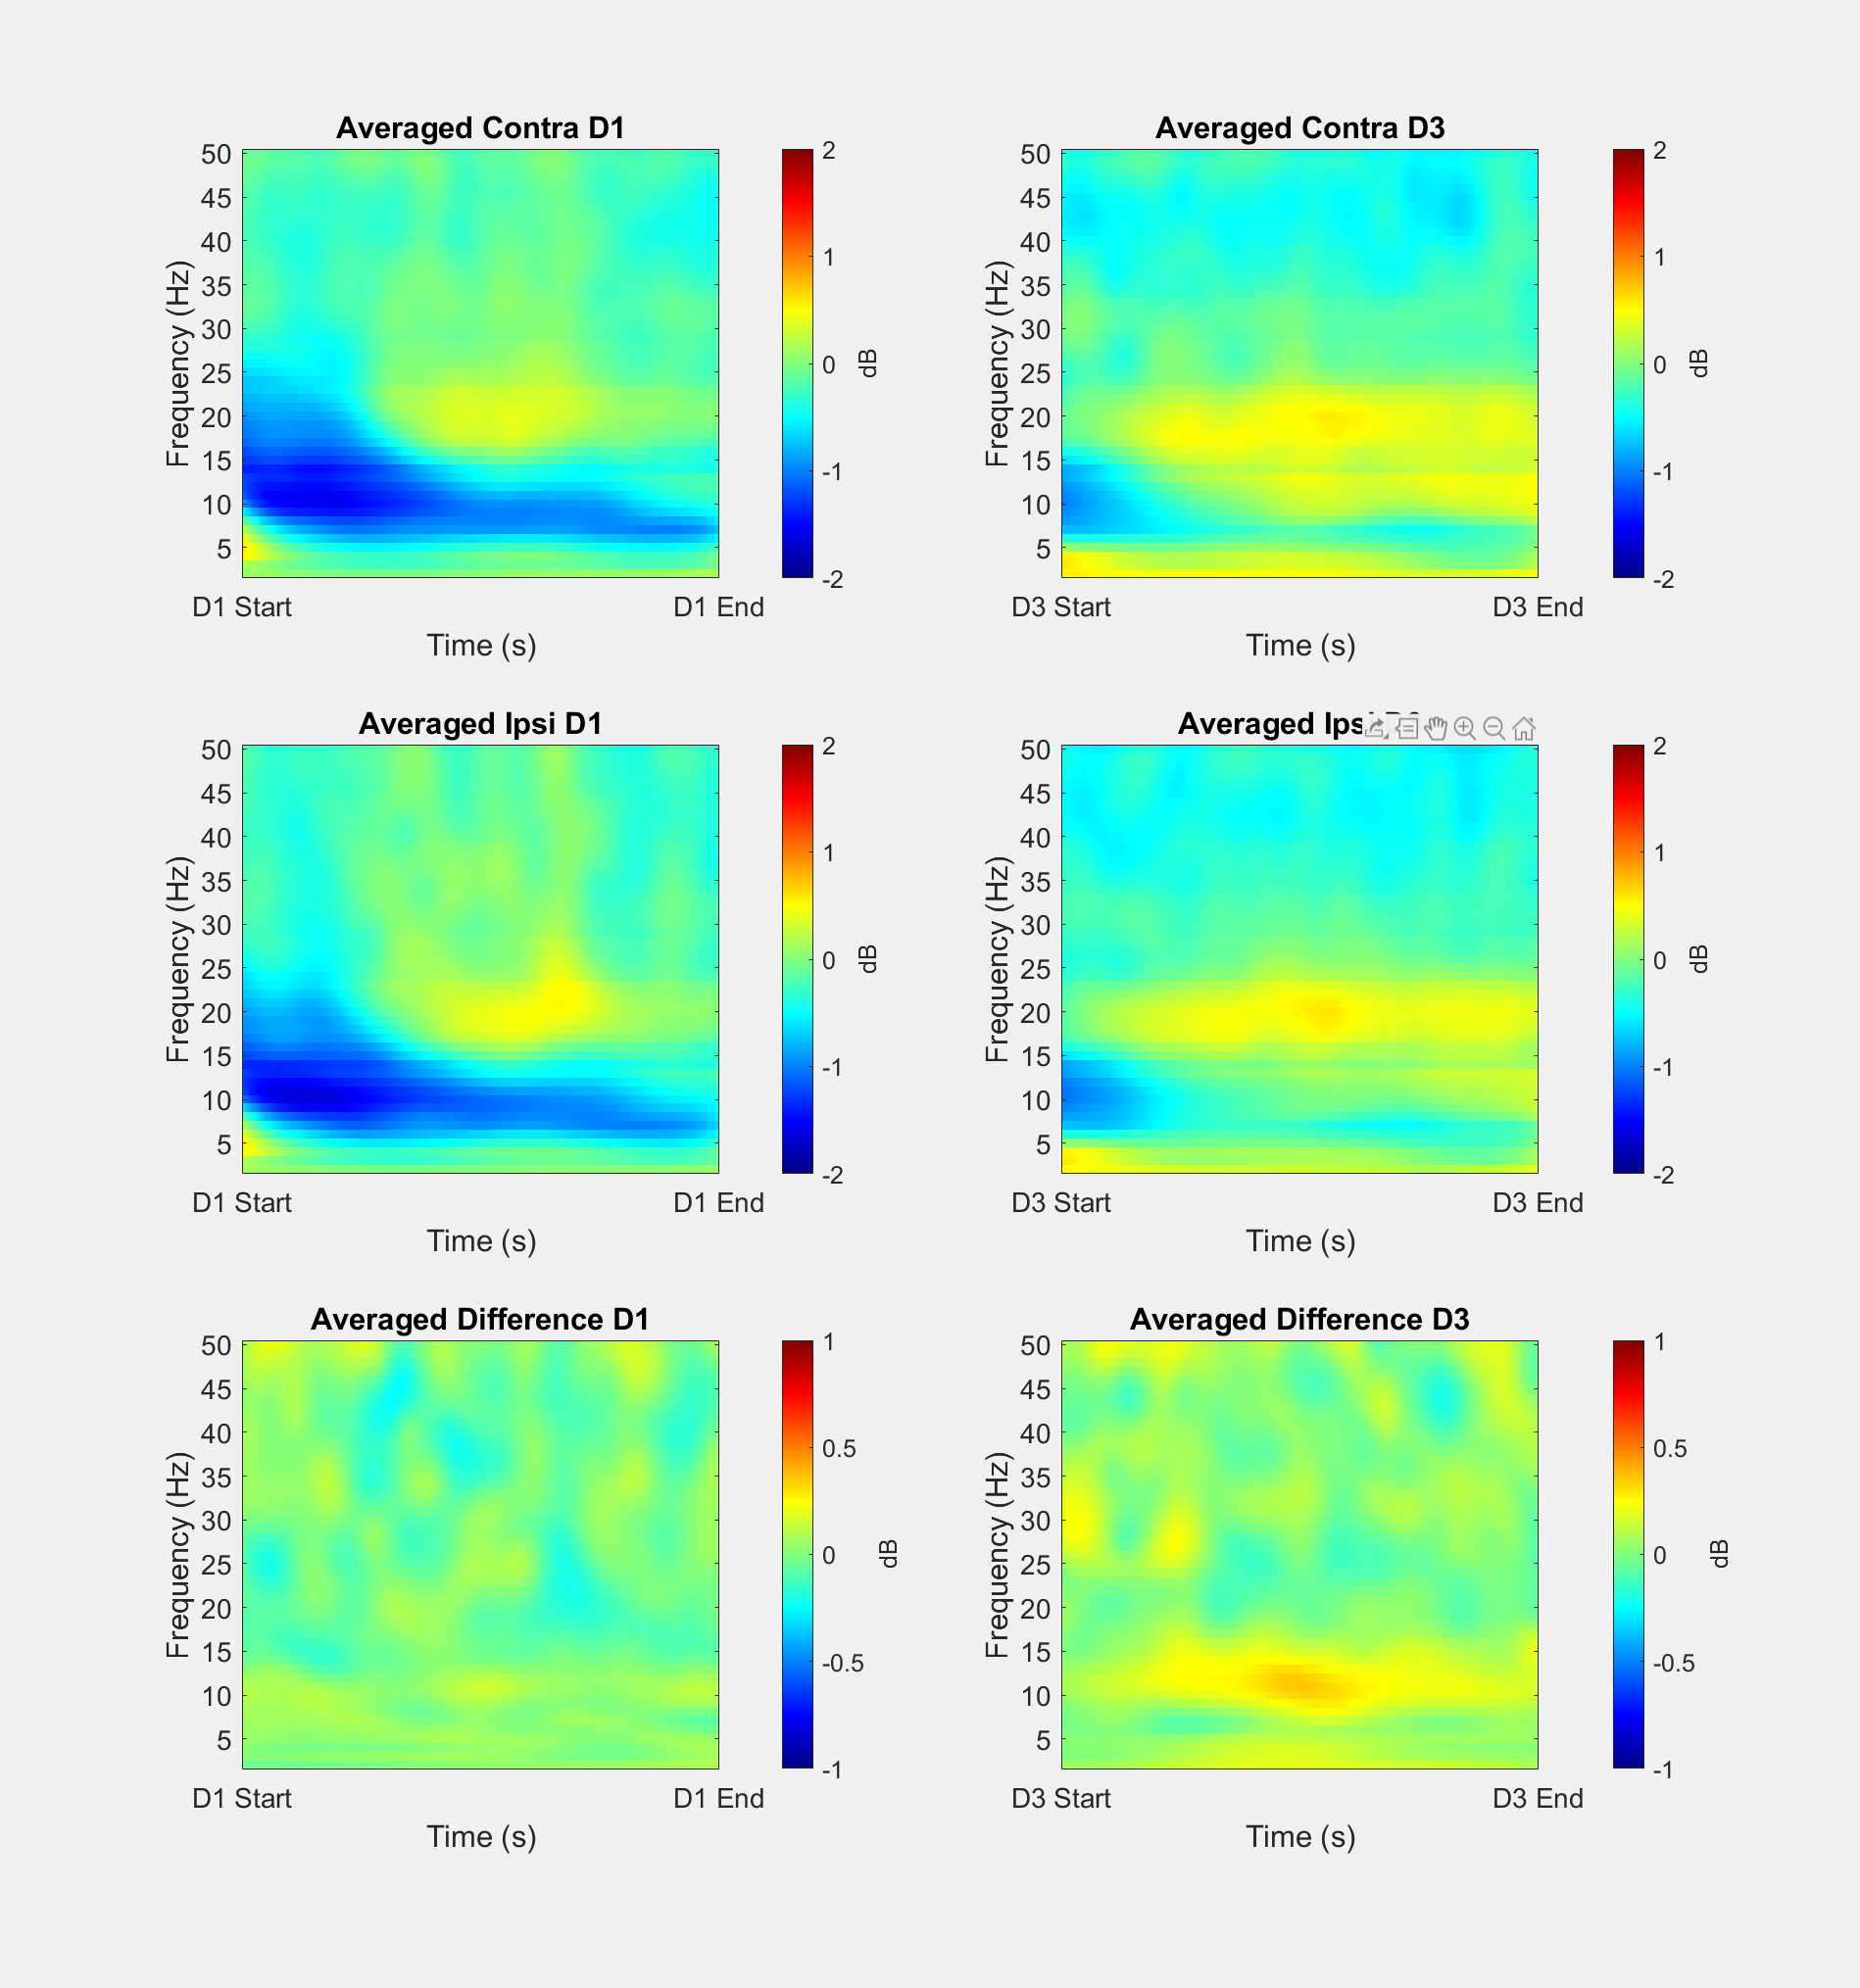


f = figure('units','normalized','outerposition',[0 0 0.5 1]);
f.Visible = 'On';
    
subplot(3,2,1)
plotfun.xlabel = {'D1 Start', 'D1 End'};
plotfun.caxis  = [-2 2];
plotfun.title  = 'Averaged Contra D1';
subplotter(combined.d1.contra,plotfun);
    
subplot(3,2,2)
plotfun.xlabel = {'D3 Start', 'D3 End'};
plotfun.caxis  = [-2 2];
plotfun.title  = 'Averaged Contra D3';
subplotter(combined.d3.contra,plotfun);
    
subplot(3,2,3)
plotfun.xlabel = {'D1 Start', 'D1 End'};
plotfun.caxis  = [-2 2];
plotfun.title  = 'Averaged Ipsi D1';
subplotter(combined.d1.ipsi,plotfun);
    
subplot(3,2,4)
plotfun.xlabel = {'D3 Start', 'D3 End'};
plotfun.caxis  = [-2 2];
plotfun.title  = 'Averaged Ipsi D3';
subplotter(combined.d3.ipsi,plotfun);
    
subplot(3,2,5)
plotfun.xlabel = {'D1 Start', 'D1 End'};
plotfun.caxis  = [-1 1];
plotfun.title  = 'Averaged Difference D1';
subplotter(combined.d1.difference,plotfun);
    
subplot(3,2,6)
plotfun.xlabel = {'D3 Start', 'D3 End'};
plotfun.caxis  = [-1 1];
plotfun.title  = 'Averaged Difference D3';
subplotter(combined.d3.difference,plotfun);
    
saveas(gcf,[imgpath filesep '_' version 'Combined_diffplot.png']);

function subplotter(data,plotfun)

imagesc(squeeze(data.powspctrm));
set(gca,'ydir','normal');
xticks([1 length(data.time)]);
xticklabels(plotfun.xlabel);

foi     = data.freq;
foi_idx = 1:length(foi);
foiticks = foi_idx(ismember(foi,5:5:50));

yticks(foiticks);
yticklabels(foi(foiticks));
y = colorbar;
ylabel(y,'dB');

caxis(plotfun.caxis);
colormap jet
title(plotfun.title);
ylabel('Frequency (Hz)');
xlabel('Time (s)');
set(gca,'Fontsize',14);

end